# Actividad Extra

### Elaborado por: Daniel Alfredo Barreras Meraz  -   A01254805

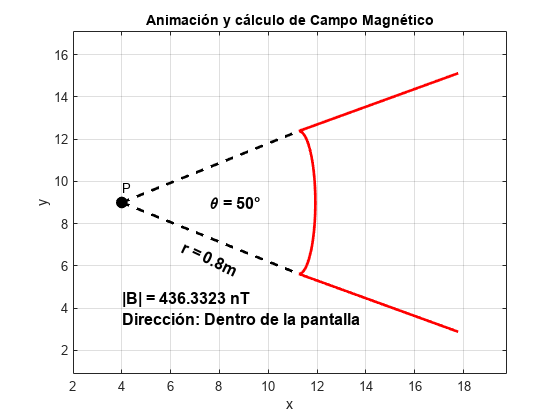

angulo = 50; % ángulo en grados
Corriente = 4; %Corriente que circula
radio = 0.8; % radio en metros
x1 = 4; y1 = 9; % coordenadas del vértice
conversion = 10; % 1 unidad en la cuadrícula equivale a 0.1 metros
x2 = x1 + radio*conversion*cosd(angulo/2); % coordenada x donde terminan las líneas
y3 = y1 + radio*conversion*sind(angulo/2); % coordenada y donde termina la primera línea
y4 = y1 - radio*conversion*sind(angulo/2); % coordenada y donde termina la segunda línea
plot([x1 x2],[y1 y3],'--k','LineWidth',2) % graficar la primera línea
hold on
plot([x1 x2],[y1 y4],'--k','LineWidth',2) % graficar la segunda línea
plot(x1,y1,'.k','MarkerSize',30) % graficar el vértice
text(x1,y1+0.7,'P') % agregar la letra "P" encima del vértice

% Agregar una curva suave entre los puntos finales de las líneas
xc = x2; yc = (y3+y4)/2; % centro de la curva
a = abs(y3-y4)/2; % semieje mayor de la elipse
b = a/5; % semieje menor de la elipse
f = @(x,y) ((x-xc).^2)/b^2 + ((y-yc).^2)/a^2 - 1;
fimplicit(f, [x2 x2+2*b y4 y3], '-r', 'LineWidth', 2)

% Agregar dos líneas que continúen con la dirección y sentido de las líneas punteadas
x3 = x2 + 0.9*(x2-x1); % coordenada x donde terminan las nuevas líneas
m1 = (y3-y1)/(x2-x1); % pendiente de la primera línea
m2 = (y4-y1)/(x2-x1); % pendiente de la segunda línea
y5 = y3 + 0.9*m1*(x3-x2); % coordenada y donde termina la primera nueva línea
y6 = y4 + 0.9*m2*(x3-x2); % coordenada y donde termina la segunda nueva línea
plot([x2 x3],[y3 y5],'-r','LineWidth',2) % graficar la primera nueva línea
plot([x2 x3],[y4 y6],'-r','LineWidth',2) % graficar la segunda nueva línea

% Agregar un texto debajo de la línea punteada inferior que indique el valor del radio, paralelo a la línea punteada inferior y centrado en ella.
text((x1+x2)/2, (y1 + y4)/2-1, ['r = ' num2str(radio) 'm'], 'Rotation', atand(m2), 'HorizontalAlignment', 'center', 'FontWeight', 'bold', "FontSize", 12)

% Agregar una línea curva entre las líneas punteadas que indique el valor del ángulo.
text((x1 + x2)/2, (y3 + y4)/2, ['\theta = ' num2str(angulo) '°'], "FontWeight", "bold",  "FontSize", 12)

% Calcular la magnitud del campo magnético P

S = radio*angulo*(2*pi/360);
B = (10^-7)*(Corriente/radio^2)*S*10^9;

% Agregar un texto debajo del punto P que indique el valor de la magnitud del campo magnético P
text(x1, y1/2, ['|B| = ' num2str(B) ' nT'], "FontWeight", "bold",  "FontSize", 12)
text(x1, y1/2-1, "Dirección: Dentro de la pantalla", "FontWeight", "bold",  "FontSize", 12)


xlabel('x')
ylabel('y')
title('Animación y cálculo de Campo Magnético')
axis([min([x1 x2 x3])-2 max([x1 x2 x3])+2 min([y1 y3 y4 y5 y6])-2 max([y1 y3 y4 y5 y6])+2])
grid on % agregar una cuadrícula


% Agregar una animación de una flecha que recorra toda la línea sólida de arriba de arriba a abajo, luego recorra la curva suave y al final recorra la línea sólida de abajo de arriba a abajo
n = 60; % número de pasos en la animación

% Calcular las coordenadas x e y de la línea sólida de arriba en cada paso de la animación
xq1 = linspace(x3, x2, n/3);
yq1 = linspace(y5, y3, n/3);
uq1 = diff(xq1); uq1 = [uq1 uq1(end)];
vq1 = diff(yq1); vq1 = [vq1 vq1(end)];

% Calcular las coordenadas x e y de la curva suave en cada paso de la animación
x_min = xc;
x_max = xc + b;
xq2 = linspace(x_min, x_max, n/3);
yq2 = yc + a*sqrt(1 - ((xq2-xc)/b).^2);
uq2 = diff(xq2); uq2 = [uq2 uq2(end)];
vq2 = diff(yq2); vq2 = [vq2 vq2(end)];

x_min = xc - b;
x_max = xc;
xq3 = linspace(x_min, x_max, n/3);
yq3 = yc - a*sqrt(1 - ((xq3-xc)/b).^2);
uq3 = diff(xq3); uq3 = [uq3 uq3(end)];
vq3 = diff(yq3); vq3 = [vq3 vq3(end)];

% Calcular las coordenadas x e y de la línea sólida de abajo en cada paso de la animación
xq4 = linspace(x2, x3, n/3);
yq4 = linspace(y4, y6, n/3);
uq4 = diff(xq4); uq4 = [uq4 uq4(end)];
vq4 = diff(yq4); vq4 = [vq4 vq4(end)];

h = quiver(xq1(1), yq1(1), uq1(1), vq1(1), 'MaxHeadSize', 2, 'AutoScaleFactor', 1000, 'AutoScale', 'off', 'Color', 'b', 'LineWidth', 12);

ht = []; % crear un vector vacío para almacenar los identificadores de los objetos de texto

for i = 2:n+n/3
    if i <= n/3
        set(h, 'XData', xq1(i), 'YData', yq1(i), 'UData', uq1(i), 'VData', vq1(i)) % actualizar la posición y dirección de la flecha para recorrer la línea sólida de arriba
        ht = text(xq1(i), yq1(i)-0.8, 'I', 'FontSize', 16); % agregar el texto "I" debajo de la flecha
    elseif i <= 2*n/3
        set(h, 'XData', xq2(i-n/3), 'YData', yq2(i-n/3), 'UData', uq2(i-n/3), 'VData', vq2(i-n/3)) % actualizar la posición y dirección de la flecha para recorrer la curva suave
        ht = text(xq2(i-n/3)+0.8, yq2(i-n/3), 'I', 'FontSize', 16); % agregar el texto "I" a la derecha de la flecha
    elseif i <= n
        set(h, 'XData', xq3(i-2*n/3), 'YData', yq3(i-2*n/3), 'UData', uq3(i-2*n/3), 'VData', vq3(i-2*n/3)) % actualizar la posición y dirección de la flecha para recorrer la curva suave
        ht = text(xq3(i-2*n/3)+0.8, yq3(i-2*n/3), 'I', 'FontSize', 16); % agregar el texto "I" a la derecha de la flecha
    else
        set(h, 'XData', xq4(i-n), 'YData', yq4(i-n), 'UData', uq4(i-n), 'VData', vq4(i-n)) % actualizar la posición y dirección de la flecha para recorrer la línea sólida de abajo
        ht = text(xq4(i-n), yq4(i-n)+0.8, 'I', 'FontSize', 16); % agregar el texto "I" arriba de la flecha
    end
    drawnow % actualizar el gráfico
    pause(0.16) % pausar por un corto tiempo para crear el efecto de animación
    delete(ht) % eliminar el objeto de texto antes de calcular el siguiente objeto quiver
end

delete(h)